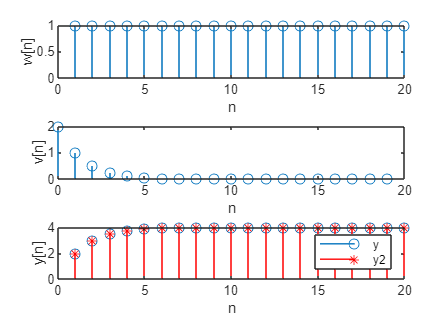

clear variables

x=@(n)(n>=1);
v=@(n)((0.5).^(n-1)).*(n>=0);
sx=1; ex=20; dtx=sx:ex;
sv=0; ev=19; dtv=sv:ev;
dty=sx+sv:ex;
y=conv(double(x(dtx)), v(dtv));
subplot(3, 1, 1); stem(dtx, x(dtx)); xlabel('n'); ylabel('w[n]');
subplot(3, 1, 2); stem(dtv, v(dtv)); xlabel('n'); ylabel('v[n]');
subplot(3, 1, 3); stem(dty, y(1:length(dty))); hold on;
y2=(4-((0.5).^(dty-2))).*(dty>=1);
stem(dty, y2, '*r'); xlabel('n'); ylabel('y[n]');
legend('y', 'y2')